% Problem set 2
% C Burgess & K Furman
% Updated 220725

## ----------------------- REVIEW: TYPES OF VARIABLES -----------------------

% Some variables are not numbers! For example, experimental groups or
% biological sex could be stored in an array of letters or words

% Below is some example data and code to work with different variable types

Experimental_group = ['a'; 'a'; 'b'; 'b']

Experimental_group = 4×1 char array
    'a'
    'a'
    'b'
    'b'


Results = [100; 98; 34; 29]

Results =    100
    98
    34
    29



% If we want to find the results for those in experimental group a,
% first we will find where the 'a' subjects are

Group_a = find(Experimental_group == 'a')

Group_a =      1
     2



% then we use those locations to index into the Results variable, figuring
% out specifically the results for those assigned group a.

Group_a_results = Results(Group_a)

Group_a_results =    100
    98



% You can also do the above two things in one line, like this:

Group_a_results = Results(Experimental_group == 'a')

Group_a_results =    100
    98



% there are generally many different ways to approach a problem in Matlab.

% You can find more here on characters and strings:
% https://www.mathworks.com/help/matlab/characters-and-strings.html

## ----------------------- PROBLEM SET #2 INTRODUCTION -----------------------

Import problem_set_2_data

% You can drag the .mat file into your Workspace
% You can also use the 'load' function (type 'help load' below to see how
% to use that function)
load 'Bootcamp_problem_set_2_data.mat'
% Here is an explanation of the data for this problem set:

    % It contains three vectors, each of which contains data for a
    % different property of each
        % Biological sex (M/F) ?  strings ?m? or ?f?
        % Mass (g)
        % Tail length (mm)

## ----------------------- PROBLEM SET #2.1 -----------------------

Analyses:

% Calculate average tail length
% Calculate average mass by sex
meanTailLength = mean(Tail_length)

meanTailLength = 88.1500

meanMassMale = mean(Mass(Sex == 'm'))

meanMassMale = 30.7000

meanMassFemale = mean(Mass(Sex == 'f'))

meanMassFemale = 26.8000

## space to work on analyses

## ----------------------- REVIEW: PLOTTING DATA -----------------------

% Here is some sample data to plot
Group_1 = [2 4 7 2 4 8]

Group_1 =      2     4     7     2     4     8


Group_2 = [3 8 7 9 4 7]

Group_2 =      3     8     7     9     4     7



%here we take the means of those group, saving them in a new array
Means_to_plot = [mean(Group_1) mean(Group_2)]

Means_to_plot =     4.5000    6.3333


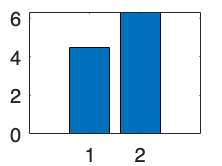


% Make a bar plot with those means
figure;
bar(Means_to_plot)

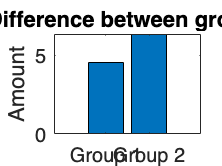


% We should add information to help the viewer interpret the figure
figure;
bar(Means_to_plot)
set(gca,'XTickLabel',{'Group 1','Group 2'})
ylabel('Amount')
title('Difference between groups')


% you can also do things like change the colors or thickness of the bars.

% Here you can find more on plotting in Matlab:
% https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html

## ----------------------- PROBLEM SET #2.2 -----------------------

Analyses:

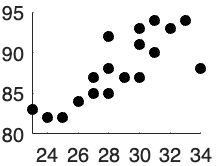

% Make a plot to visualize relationship between tail length and mass
%   -Think: what is the best plot for this?
figure;
scatter(Mass, Tail_length, 30, 'black', 'filled')

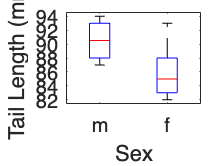



% Visualize sex differences in mass
%   -Think: what is the best plot for this?
figure;
boxplot(Tail_length, Sex)
xlabel('Sex')
ylabel('Tail Length (mm)')

## space to work on analyses

## ----------------------- INTRO: STATISTICS -----------------------

% Statistics can be done in Matlab
% We can run a ttest on the groups we created earlier

% Here we use the function, ttest2, to check whether the difference in
% the example groups from before is statistically significant
[h,p]  = ttest2(Group_1,Group_2)

h = 0

p = 0.2198


%this function outputs:
    % h, which is whether the null-hypothesis was rejected
    % p, which is the p value

% More on Matlab t-tests here:
% https://www.mathworks.com/help/stats/ttest2.html

## ----------------------- PROBLEM SET #2.3 -----------------------

Analyses:

% Test to see if the difference in mass by sex is statistically significant
[h1, p1] = ttest2(Mass, Sex)

h1 = 1

p1 = 9.9557e-43

## space to work on analyses

## ----------------------- EXTRA PROBLEM (CHALLENGING) -----------------------

% Having the p value reflected in the title of the graph could be useful.
% Try to make a plot with th p-value reflected in the title.

% There are functions that can convert numbers-to-strings and 
% strings-to-numbers
%HOW THE FUCK DO YOU PLOT THE SIGNIFICANCE MARKER ON A BOXPLOT
figure;
boxplot(Tail_length, Sex)

xlabel('Sex')
ylabel('Tail Length (mm)')

annotation()